# Lab Activity 5

### Agam Goyal ###

## Item 2

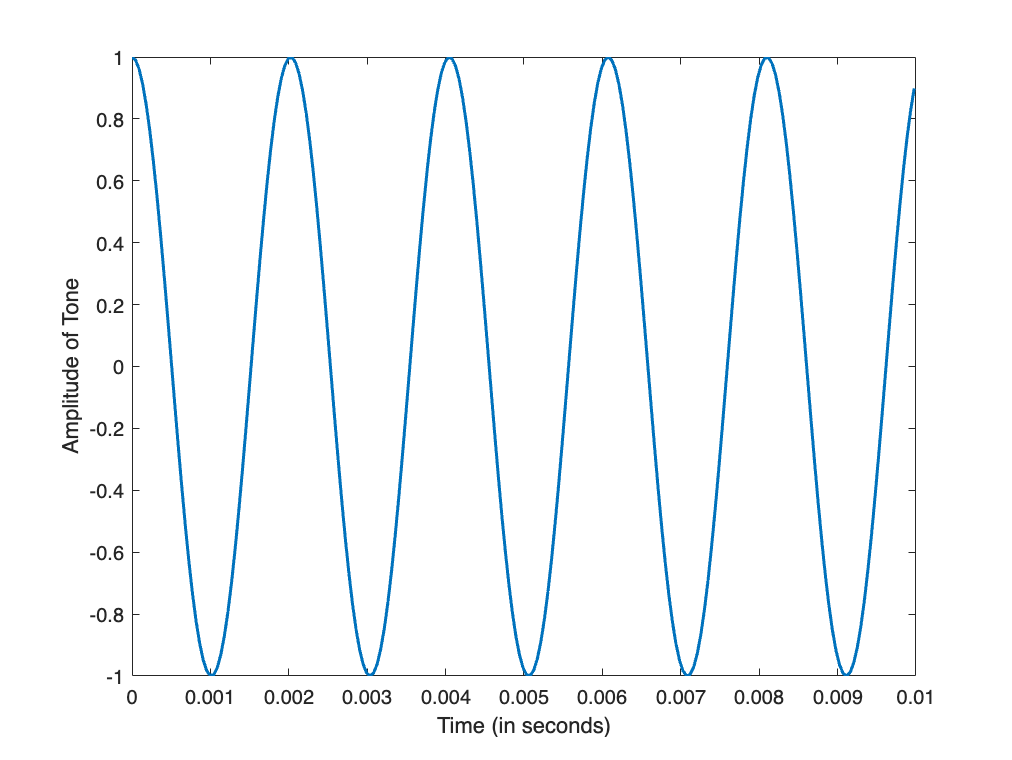

% Write and Call key2note.m function
fs = 22050;
keynum = 51;
dur = 0.01;
X = 1;

tone = key2note(X, keynum, dur, fs);
tt = 0:(1/fs):dur;

% Plot Function Output
plot(tt,tone, 'LineWidth',1.5)
xlabel('Time (in seconds)')
ylabel('Amplitude of Tone')

## Item 3: play_scale_starter.m code

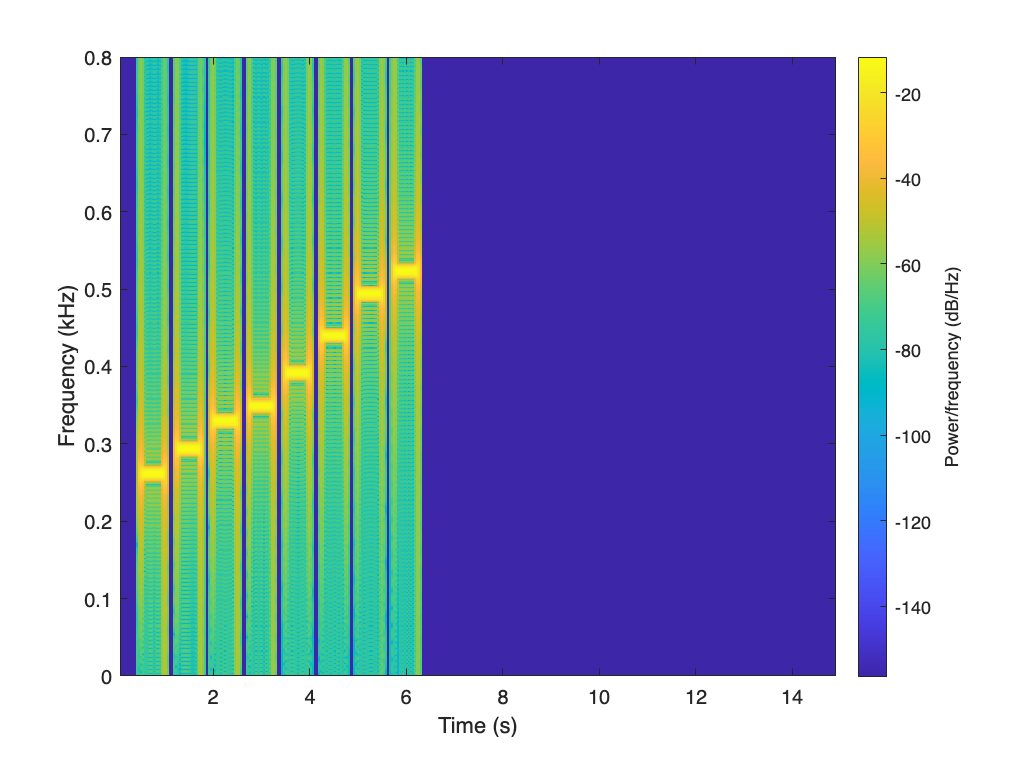

%--- play_scale.m
%---
scale.keys = [ 40 42 44 45 47 49 51 52 ];
%--- NOTES: C D E F G A B C
% key #40 is middle-C
%

X = 1;
fs = 22050;
beats_per_min = 60;

beats_per_sec = beats_per_min/60;
sec_per_beat = 1/beats_per_sec;
sec_per_pulse = sec_per_beat/4;

% duration of each note in scale
pulses_per_note = 2;
scale.durations(1:length(scale.keys)) = pulses_per_note*sec_per_pulse; % in seconds

% start times of each note in scale
scale.noteStart = [1:length(scale.keys)]*3; % start each note three pulses later

% allocate up to sixty pulses total
tt = 0:(1/fs):60*sec_per_pulse;
xx = zeros(1, length(tt));

for kk = 1:length(scale.keys)
    keynum = scale.keys(kk);
    
    % Complete the following line of code and uncomment to run
    tone = key2note(X, keynum, scale.durations(kk), fs);
    note_indx_start = round((scale.noteStart(kk)-1)*sec_per_pulse*fs);
    note_indx_stop = note_indx_start+length(tone)-1;
    xx(note_indx_start:note_indx_stop) = xx(note_indx_start:note_indx_stop) + tone; %<=== Insert the note
end

soundsc( xx, fs )

spectrogram(xx, 4096, 3200, 16384, fs, 'yaxis')
ylim([0,0.8])